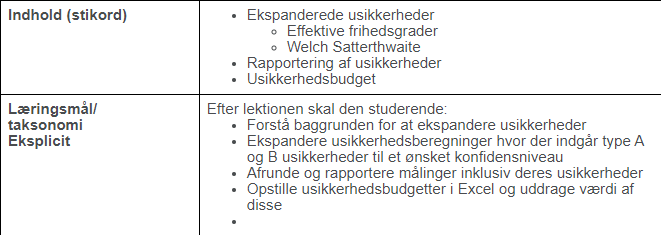

% Opgave 4.69 vidst nok

clc; clear;

x1 = [5 5 5 5 5 5 5 5 5 5]

x1 =      5     5     5     5     5     5     5     5     5     5


x2 = [5 5 5 5]

x2 =      5     5     5     5


% 
 KonfidensIntervalNormal(x1,95,0.12,[])

Da populations-standardafvigelsen er kendt, vides det pr. den
centrale grænseværdi sætning at stikprøven er standard normalfordelt
Først regnes stikprøvemiddelværdien


$$\bar{y}=\frac{\Sigma \,y_{i}}{n}$$

y_bar_x =      5


Z værdien skal findes, vha. følgende formel


$$\frac{z_{\alpha }}{2}=\mathrm{norminv}\,\frac{\alpha }{2}$$

test_vals =   -1.959963984540054
   1.959963984540054


$$\mathrm{Upper}=\bar{y}+\frac{\frac{z_{\alpha }}{2}\,\sigma }{\sqrt{n}}$$

upper_t =    4.925624596123453


$$\mathrm{Lower}=\bar{y}-\frac{\frac{z_{\alpha }}{2}\,\sigma }{\sqrt{n}}$$

lower_t =    5.074375403876547


Ingen sand middelværdi opgivet
    Interval    Værdier    Test type       Testværdier        Værdi     Deskriptorer
    ________    _______    _________    _________________    _______    ____________

    "Nedre"     4.9256     "Z nedre"    -1.95996398454005    "y_bar"           5    
    "Øvre"      5.0744     " Z øvre"     1.95996398454005    "sigma"        0.12    



 KonfidensIntervalNormal(x2,95,0.12,[])

Da populations-standardafvigelsen er kendt, vides det pr. den
centrale grænseværdi sætning at stikprøven er standard normalfordelt
Først regnes stikprøvemiddelværdien


$$\bar{y}=\frac{\Sigma \,y_{i}}{n}$$

y_bar_x =      5


Z værdien skal findes, vha. følgende formel


$$\frac{z_{\alpha }}{2}=\mathrm{norminv}\,\frac{\alpha }{2}$$

test_vals =   -1.959963984540054
   1.959963984540054


$$\mathrm{Upper}=\bar{y}+\frac{\frac{z_{\alpha }}{2}\,\sigma }{\sqrt{n}}$$

upper_t =    4.882402160927596


$$\mathrm{Lower}=\bar{y}-\frac{\frac{z_{\alpha }}{2}\,\sigma }{\sqrt{n}}$$

lower_t =    5.117597839072404


Ingen sand middelværdi opgivet
    Interval    Værdier    Test type       Testværdier        Værdi     Deskriptorer
    ________    _______    _________    _________________    _______    ____________

    "Nedre"     4.8824     "Z nedre"    -1.95996398454005    "y_bar"           5    
    "Øvre"      5.1176     " Z øvre"     1.95996398454005    "sigma"        0.12    



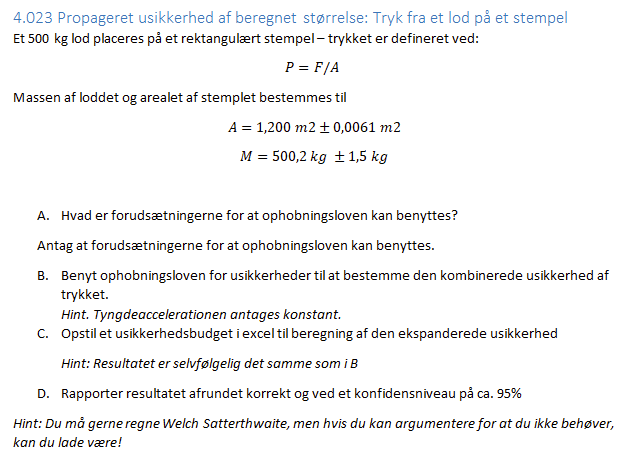

clc; clear all;
u = symunit;

A = 1.2 * u.m^2;
M = 500.2 * u.kg;

fejl_A = 0.0061 * u.m^2;
fejl_M = 1.5*u.kg;

g = 9.81 * u.m/u.s^2;


% Formel
syms m A1
func = m*g/A1;


U1 = Ophobningsloven(func, [m A1], [M A], [fejl_M, fejl_A]);
U1 = vpa(unitConvert(U1, u.Pa), 3)

$$U1 = 24.1\,\mathrm{Pa}$$




P = M*g/A;

P = double(separateUnits(P))

P = 4.0891e+03

U1 = double(separateUnits(U1))

U1 = 24.1339

Pp = P-U1:0.1:P+U1

Pp = 1.0e+03 *

    4.0650    4.0651    4.0652    4.0653    4.0654    4.0655    4.0656    4.0657    4.0658    4.0659    4.0660    4.0661    4.0662    4.0663    4.0664    4.0665    4.0666    4.0667    4.0668    4.0669    4.0670    4.0671    4.0672    4.0673    4.0674    4.0675    4.0676    4.0677    4.0678    4.0679    4.0680    4.0681    4.0682    4.0683    4.0684    4.0685    4.0686    4.0687    4.0688    4.0689    4.0690    4.0691    4.0692    4.0693    4.0694    4.0695    4.0696    4.0697    4.0698    4.0699




% %KonfidensIntervalNormal(P, 95, U1, [])





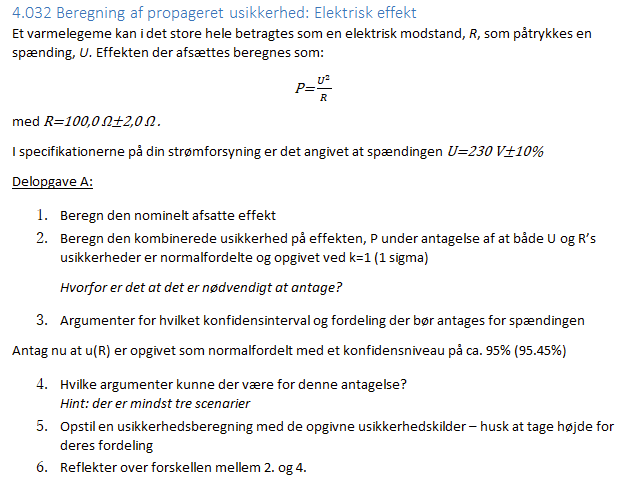

clc; clear;
u = symunit;

syms U R alpha
func = U^2/R

$$func = \frac{U^{2}}{R}$$

symvars = [U, R]

$$symvars = \left(\begin{array}{cc} U & R \end{array}\right)$$


Robs = 100 * u.ohm;
Uobs = 230 * u.V;

var_list = [Uobs, Robs]

$$var\_list = \left(\begin{array}{cc} 230\,V & 100\,\Omega \end{array}\right)$$


% Opgave A Nominelt afsatte effekt
Pnom = Uobs^2/Robs;



R_fejl = 2 * u.ohm;
U_fejl = 0.1 * Uobs;

% Opgave B

% Hvor der ikke er taget højde for fordeling
U2 = Ophobningsloven(func, symvars, var_list, [U_fejl, R_fejl]);
U2 = vpa(unitConvert(U2, u.W), 3)

$$U2 = 106.0\,W$$


% Usikkerhedsformler
u_t = alpha/sqrt(6);
u_f = alpha/sqrt(3);
u_u = alpha/sqrt(2);

% Fejl fordelinger
u_R = subs(u_u, alpha, R_fejl);
u_U = subs(u_t, alpha, U_fejl);

error_list = [u_U, u_R]

$$error\_list = \left(\begin{array}{cc} \frac{23\,\sqrt{6}}{6}\,V & \sqrt{2}\,\Omega \end{array}\right)$$



% Hvor der er taget højde for fordeling (parallelitet er inkluderet)
U1 = Ophobningsloven(func, symvars, var_list, error_list);
U1 = vpa(unitConvert(U1, u.W), 3)

$$U1 = 43.8\,W$$


Veff = WelchSatterthwaite(1.26, [0.75 0.59 0.82], [10 5 inf])

WS = 0.0352

WS =     0.0352    0.0303


WS =     0.0352    0.0303         0


Veff = 38.5101


U = 1.26;
u = [0.75 0.59 0.82];
ns = [10 5 inf];

for i = 1:length(u)
   WS(i) = u(i)^4/(ns(i)-1)
end

WS =     0.0352    0.0303         0


WS =     0.0352    0.0303         0


WS =     0.0352    0.0303         0



U^4/sum(WS)

ans = 38.5101

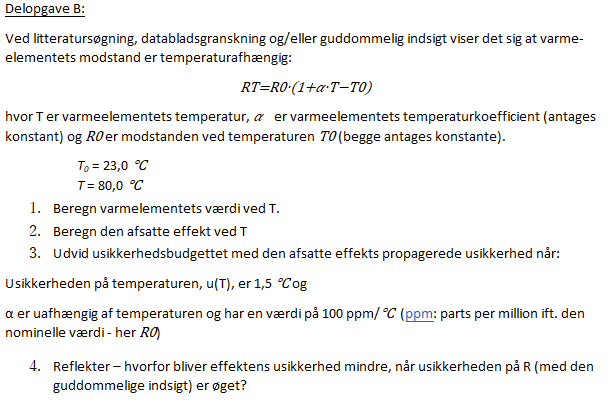

clc; clear all;
u = symunit;

syms R0 alpha T T0

func = R0*(1 + alpha*T - T0)

$$func = R_{0}\,\left(T\,\alpha -T_{0}+1\right)$$


% Værdier
T0 = 23;
T = 80;
alpha = 100;
R0 = 5;















